% Initializing script
clc, clf, clear

constants;

% Design space for optimization
n_data = 10;    % number of data points
P_c = linspace(0.5*P_c_ref, 1.5*P_c_ref, n_data); % chamber pressure range (Pa)
A_t = linspace(0.5*A_t_ref, 1.5*A_t_ref, n_data); % throat area range (m2)
A_e = linspace(0.5*A_e_ref, 1.5*A_e_ref, n_data); % exit area range (m2)

## Convexity analysis

% Initializing objective function values
total_mass_P_c = zeros(1, length(P_c)); 
total_mass_A_t = zeros(1, length(A_t));
total_mass_A_e = zeros(1, length(A_e));

% Calculating objective function value w.r.t each design variables
for i = 1:length(P_c)
    total_mass_P_c(i) = calc_objective([P_c(i)/P_c_ref, 1, 1]);
    total_mass_A_t(i) = calc_objective([1, A_t(i)/A_t_ref, 1]);
    total_mass_A_e(i) = calc_objective([1, 1, A_e(i)/A_e_ref]);
end

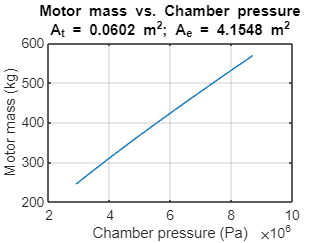

% Plotting results
plot(P_c, total_mass_P_c)
xlabel('Chamber pressure (Pa)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Chamber pressure' 'A_t = 0.0602 m^2; A_e = 4.1548 m^2'})
grid on

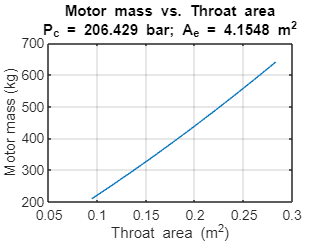


plot(A_t, total_mass_A_t)
xlabel('Throat area (m^2)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Throat area' 'P_c = 206.429 bar; A_e = 4.1548 m^2'})
grid on

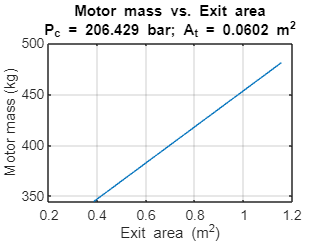


plot(A_e, total_mass_A_e)
xlabel('Exit area (m^2)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Exit area' 'P_c = 206.429 bar; A_t = 0.0602 m^2'})
grid on

## Calculating objective function in design space

% Initializing objective and constraint function values
total_mass_val = zeros(length(P_c), length(A_t), length(A_e));
ineq_constraint = zeros(length(P_c), length(A_t), length(A_e));
eq_constraint = zeros(length(P_c), length(A_t), length(A_e));

% Calculating objective and constraint functions
for i = 1:length(P_c)
    for j = 1:length(A_t)
        for k = 1:length(A_e)
            x_scaled = scale([P_c(i), A_t(j), A_e(k)], x_ref);
            total_mass_val(i, j, k) = calc_objective(x_scaled);
            [ineq_constraint(i,j,k), eq_constraint(i,j,k)] = calc_constraints(x_scaled);
        end
    end
end

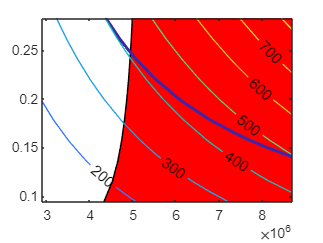

% Example plot
clf
i = 4;
contourf(P_c, A_t, ineq_constraint(:, :, i), [0,0], 'FaceColor', '#FF0000');
hold on
[M,c] = contour(P_c, A_t, eq_constraint(:, :, i), [0,0]);
c.LineWidth = 2;
contour(P_c, A_t, total_mass_val(:,:, i), 'ShowText','on')
hold off

%% Sample SQP conditions
% Linear constraints
A = []; 
b = [];
Aeq = [];
beq = [];

% Design variable bounds
lb = [0.1, 0.1, 0.1];
ub = [10, 10, 10];

options = optimoptions('fmincon','Display','iter','Algorithm','sqp');
x0 = [1, 1, 1];
[x, fval, exitflag, output, lambda] = fmincon(@calc_objective_test, x0, ...
    A, b, Aeq, beq, lb, ub, @calc_constraints, options)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    3.116809e+04     6.872e-02     1.000e+00     0.000e+00     2.655e+04  
    1           8    7.344800e+03     8.200e-01     1.000e+00     1.559e+00     5.856e+02  
    2          13    1.038875e+04     4.439e-02     7.000e-01     7.379e+00     2.732e+03  
    3          19    1.083440e+04     2.703e-02     4.900e-01     1.727e+00     2.170e+03  
    4          30    1.092015e+04     2.494e-02     8.235e-02     4.527e-01     1.979e+03  
    5          39    1.111914e+04     2.095e-02     1.681e-01     3.378e-01     1.904e+03  
    6          47    1.136313e+04     1.635e-02     2.401e-01     4.870e-01     1.659e+03  
    7          54    1.167397e+04     1.500e-02     3.430e-01     3.048e-01     1.504e+03  
    8          60    1.200155e+04     1.183e-02     4.900e-01     4.044e-01     1.

x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 1

output = struct with fields:
         iterations: 13
          funcCount: 80
          algorithm: 'sqp'
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 2.060585e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 1.345479e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
    constrviolation: 1.3455e-11
           stepsize: 1.1278e-04
       lssteplength: 1
      firstorderopt: 0.0062
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04
         lower: [3×1 double]
         upper: [3×1 double]


x = descale(x, x_ref);
fprintf('Chamber pressure = %f\nThroat area = %f\nExit area = %f\nTotal Mass = %f' ...
    , x(1), x(2), x(3), fval)

Chamber pressure = 1459198.304264
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637522

options = optimoptions('fmincon','Display','iter','Algorithm','active-set');
x0 = [0.7, 0.75, 1];
[x, fval, exitflag, output, lambda] = fmincon(@calc_objective_test, x0, ...
    A, b, Aeq, beq, lb, ub, @calc_constraints, options)


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      23117.2         0.48                                         Infeasible start point
    1      9      15375.1       0.4321          0.5    -7.04e+03     7.81e+03   
    2     14      11660.7       0.3797          0.5    -1.92e+03     3.76e+03  Hessian modified  
    3     18      9067.38       0.3718            1         -330     6.68e+04   
    4     22      11099.9      0.02442            1      6.4e+03     7.47e+03   
    5     26      12042.1      0.09297            1          434     4.58e+03   
    6     31      11616.3      0.07365          0.5         -102      1.4e+04   
    7     37      11153.4      0.06902         0.25         -347     7.29e+03   
    8     41      12202.4      0.02711            1          855     4.13e+03   
    9     45      12337.8     0.001229            1          117

x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 14
          funcCount: 61
       lssteplength: 1
           stepsize: 6.1688e-07
          algorithm: 'active-set'
      firstorderopt: 7.5712e-05
    constrviolation: 1.0980e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 6.163293e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.098011e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


x = descale(x, x_ref);
fprintf('Chamber pressure = %f\nThroat area = %f\nExit area = %f\nTotal Mass = %f' ...
    , x(1), x(2), x(3), fval)

Chamber pressure = 1459198.294291
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637523

calc_objective_test(scale(x, x_ref))

ans = 1.2429e+04

calc_objective_test(scale(x, x_ref))

ans = 1.2429e+04